clear; clc; close all;

%% =========================
% Zero joint position
% All joint angles are in radians
%% =========================
q = [0 0 0 0 0];

%% =========================
% Robot dimensions (replace with your own values)
%% =========================
b  = 2.5;
L1 = 5;
L2 = 18;
L3 = 12;
L4 = 6;

%% =========================
% Standard DH table
% Each row = [a_{i-1}, alpha_{i-1}, d_i, theta_i]
%% =========================
DH_table = [ ...
   -b,   pi/2,   L1,      q(1);
    L2,    0,     0,      q(2) + pi/2;
    L3,    0,     0,      q(3);
     0,   -pi/2,  0,      q(4) - pi/2;
     0,    0,    L4,      q(5)
];
%% =========================
% Forward kinematics
%% =========================
n = size(DH_table,1);

T = eye(4);                       % cumulative transform
origins = zeros(3,n+1);           % O0 to On
origins(:,1) = [0;0;0];           % base origin

T_all = cell(1,n);                % store cumulative transforms
z_axes = zeros(3,n+1);            % z-axis of each frame
z_axes(:,1) = [0;0;1];            % base frame z0

for i = 1:n
    a     = DH_table(i,1);
    alpha = DH_table(i,2);
    d     = DH_table(i,3);
    theta = DH_table(i,4);

    A_i = DH_std(a, alpha, d, theta);   % A_i = T_{i-1}^{i}
    T = T * A_i;                        % cumulative transform

    T_all{i} = T;
    origins(:,i+1) = T(1:3,4);          % origin of frame i
    z_axes(:,i+1) = T(1:3,3);           % z-axis of frame i expressed in frame 0
end

%% =========================
% Display final end-effector transform
%% =========================
disp('Final transformation matrix T_0^E at zero position:');

Final transformation matrix T_0^E at zero position:


disp(T);

    1.0000         0         0   -2.5000
         0    1.0000         0    0.0000
         0         0    1.0000   41.0000
         0         0         0    1.0000



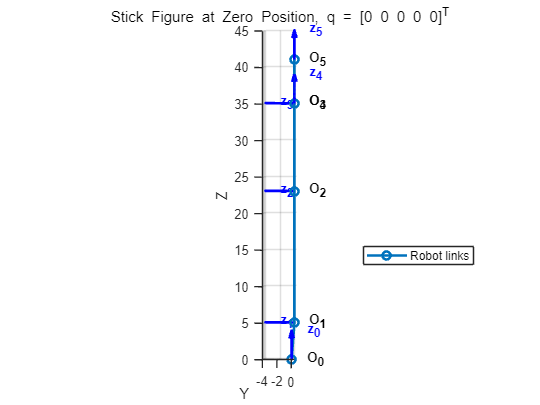


%% =========================
% Plot stick figure + z-axes
%% =========================
figure;
plot3(origins(1,:), origins(2,:), origins(3,:), '-o', ...
      'LineWidth', 2, 'MarkerSize', 6);
grid on; axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Stick Figure at Zero Position, q = [0 0 0 0 0]^T');

hold on;

% Label origins
for i = 1:(n+1)
    text(origins(1,i), origins(2,i), origins(3,i), sprintf('  O_%d', i-1), ...
        'FontSize', 10, 'FontWeight', 'bold');
end

% Plot z-axis direction of each frame
axis_scale = 4;   % adjust arrow length if needed

for i = 1:(n+1)
    quiver3(origins(1,i), origins(2,i), origins(3,i), ...
            axis_scale*z_axes(1,i), axis_scale*z_axes(2,i), axis_scale*z_axes(3,i), ...
            0, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.8);

    % label the z-axis tip
    tip = origins(:,i) + axis_scale*z_axes(:,i);
    text(tip(1), tip(2), tip(3), sprintf('  z_%d', i-1), ...
        'Color', 'b', 'FontSize', 10, 'FontWeight', 'bold');
end

legend('Robot links', 'Location', 'best');
view(45,25);


%% =========================
% Optional: print z-axis directions numerically
%% =========================
disp('Z-axis directions of each frame expressed in base frame:');

Z-axis directions of each frame expressed in base frame:


for i = 1:(n+1)
    fprintf('z_%d = [%.4f; %.4f; %.4f]\n', i-1, z_axes(1,i), z_axes(2,i), z_axes(3,i));
end

z_0 = [0.0000; 0.0000; 1.0000]
z_1 = [0.0000; -1.0000; 0.0000]
z_2 = [0.0000; -1.0000; 0.0000]
z_3 = [0.0000; -1.0000; 0.0000]
z_4 = [0.0000; 0.0000; 1.0000]
z_5 = [0.0000; 0.0000; 1.0000]


function T = DH_std(a, alpha, d, theta)
% Standard DH transform using [a_{i-1}, alpha_{i-1}, d_i, theta_i]

T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
     sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
     0,           sin(alpha),             cos(alpha),            d;
     0,           0,                      0,                     1];
end







% clear; clc; close all;
% 
% %% =========================
% % Zero joint position
% % All joint angles are in radians
% %% =========================
% q = [0 0 0 0 0];
% 
% %% =========================
% % Robot dimensions (replace with your own values)
% %% =========================
% h0 = 5.08;    % base height
% h1 = 18;   % upper arm length
% h2 = 12;   % forearm length
% h3 = 6;    % wrist link length
% b1 = 2.5;    % base offset
% 
% %% =========================
% % Standard DH table
% % Each row = [a_{i-1}, alpha_{i-1}, d_i, theta_i]
% %% =========================
% DH_table = [
%     0    0       h0    q(1);
%     b1   pi/2    0     q(2);
%     h1   0       0     q(3);
%     h2   0       0     q(4);
%     h3  -pi/2    0     q(5)
% ];
% 
% %% =========================
% % Forward kinematics
% %% =========================
% n = size(DH_table,1);
% 
% T = eye(4);                  % cumulative transform
% origins = zeros(3,n+1);      % O0 to On
% origins(:,1) = [0;0;0];      % base origin
% 
% T_all = cell(1,n);           % optional: store cumulative transforms
% 
% for i = 1:n
%     a     = DH_table(i,1);
%     alpha = DH_table(i,2);
%     d     = DH_table(i,3);
%     theta = DH_table(i,4);
% 
%     A_i = DH_std(a, alpha, d, theta);   % A_i = T_{i-1}^{i}
%     T = T * A_i;                        % cumulative transform
% 
%     T_all{i} = T;
%     origins(:,i+1) = T(1:3,4);
% end
% 
% %% =========================
% % Display final end-effector transform
% %% =========================
% disp('Final transformation matrix T_0^E at zero position:');
% disp(T);
% 
% %% =========================
% % Plot stick figure
% %% =========================
% figure;
% plot3(origins(1,:), origins(2,:), origins(3,:), '-o', ...
%       'LineWidth', 2, 'MarkerSize', 6);
% grid on; axis equal;
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% title('Stick Figure at Zero Position, q = [0 0 0 0 0]^T');
% 
% hold on;
% for i = 1:(n+1)
%     text(origins(1,i), origins(2,i), origins(3,i), sprintf('  O_%d', i-1));
% end
% 
% view(45,25);
% 
% 
% 
% 
% 
% function T = DH_std(a, alpha, d, theta)
% % Standard DH transform using [a_{i-1}, alpha_{i-1}, d_i, theta_i]
% 
% T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
%      sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
%      0,           sin(alpha),             cos(alpha),            d;
%      0,           0,                      0,                     1];
% end